clc;
close all;
clear all;

m = 0.1;
M = 0.427;
l = 0.10382;
J = 8.9432*10^-4;
g = 9.81;

alpha = m + M - (m^2*l^2)/(J+m*l^2)

alpha = 0.4723

beta = (J+m*l^2) - (m^2*l^2)/(m+M)

beta = 0.0018


% Continuous Time State Space
A = [0 1 0 0;
     0 0 -(m^2*l^2*g)/(alpha*(J+m*l^2)) 0;
     0 0 0 1;
     0 0 (m*g*l)/beta 0]   

A =          0    1.0000         0         0
         0         0   -1.1351         0
         0         0         0    1.0000
         0         0   57.6174         0


B = [0; 1/alpha; 0; -m*l/beta*(m+M)]

B =          0
    2.1171
         0
   -3.0952


C = [1 0 0 0; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0; 0]

D =      0
     0



sys_c = ss(A, B, C, D)


sys_c =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -1.135       0
   x3       0       0       0       1
   x4       0       0   57.62       0
 
  B = 
           u1
   x1       0
   x2   2.117
   x3       0
   x4  -3.095
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



% Discrete Time State Space
Ts = 0.01

Ts = 0.0100


sys_d = c2d(sys_c, Ts, 'zoh')


sys_d =
 
  A = 
               x1          x2          x3          x4
   x1           1        0.01  -5.678e-05  -1.892e-07
   x2           0           1    -0.01136  -5.678e-05
   x3           0           0       1.003     0.01001
   x4           0           0      0.5767       1.003
 
  B = 
               u1
   x1   0.0001059
   x2     0.02117
   x3  -0.0001548
   x4    -0.03098
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;

G = ss(A, B, C, D)


G =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -1.135       0
   x3       0       0       0       1
   x4       0       0   57.62       0
 
  B = 
           u1
   x1       0
   x2   2.117
   x3       0
   x4  -3.095
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


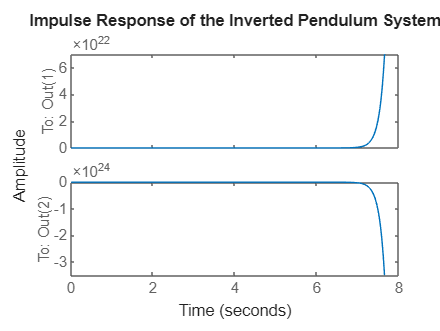

% Define your State-Space System

%define input

t  = [0:0.01:10]';    % Time vector 0 to 10 second
u = ones(size(t));

% Plot the Impulse Response
figure;
impulse(G);
title('Impulse Response of the Inverted Pendulum System');

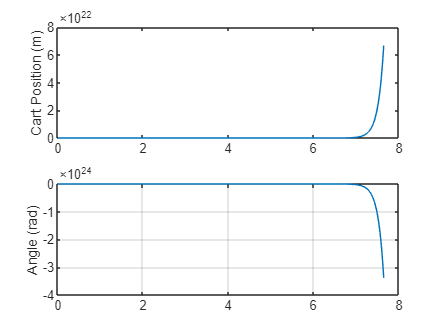


% To get the data points for custom plotting:
[y, t] = impulse(G);
% y(:,1) is Cart Position (x), y(:,2) is Pendulum Angle (theta)
subplot(2,1,1); plot(t, y(:,1)); ylabel('Cart Position (m)');
subplot(2,1,2); plot(t, y(:,2)); ylabel('Angle (rad)');
grid on;

% % 1. Run the simulation and save to variables [y, t]
% [y, t_out] = lsim(G, u, t); 
% 
% % 2. Manually plot and add the grid to each subplot
% figure;
% 
% subplot(2,1,1);
% plot(t_out, y(:,1), 'b', 'LineWidth', 1.5); % Plot Cart Position
% ylabel('Cart x (m)');
% grid on; % This will now stay visible
% 
% subplot(2,1,2);
% plot(t_out, y(:,2), 'r', 'LineWidth', 1.5); % Plot Angle
% ylabel('Angle \theta (rad)');
% grid on;